# **Electric propulsion system for a small UAV**

Run setup script to preset values.

run("setup_params.m")


FAULT INJECTION PARAMETERS

All values = 1 means healthy system


% Battery faults
R_int_base = 0.02;          % Base internal resistance (Ohms)
R_int_fault = 1;            % Multiplier (1.5-2.5 for aging)

% Motor faults
Motor_efficiency = 0.85;    % Efficiency (0.70-0.75 for degradation)

% Propeller faults
CT_fault_multiplier = 1;    % Thrust coeff (0.80-0.90 for damage)
CP_fault_multiplier = 1;    % Power coeff (1.10-1.20 for damage)

sim('uav_propulsion_dc_motor.slx');

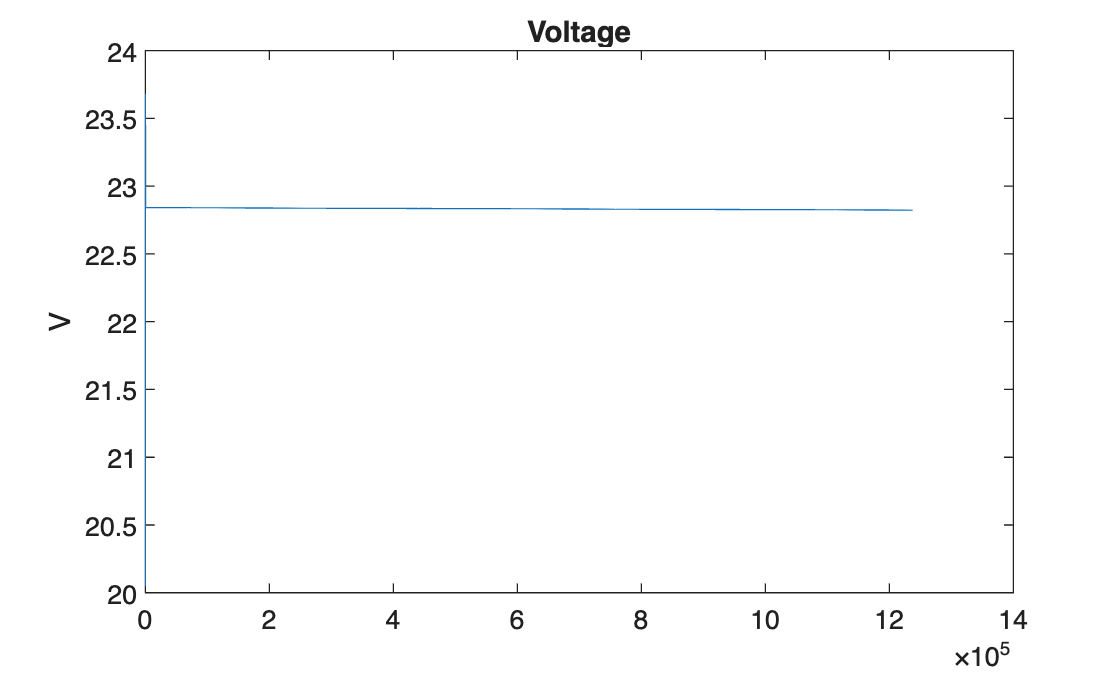

plot(out.voltage_log.Data); title('Voltage'); ylabel('V');

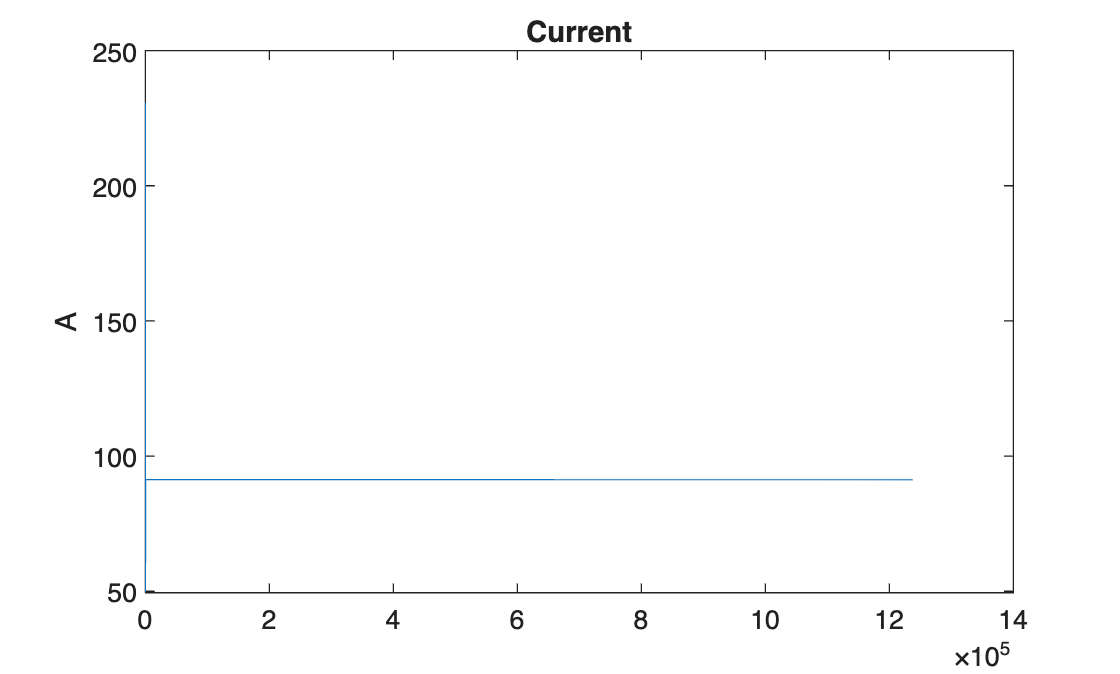

plot(out.current_log.Data); title('Current'); ylabel('A');

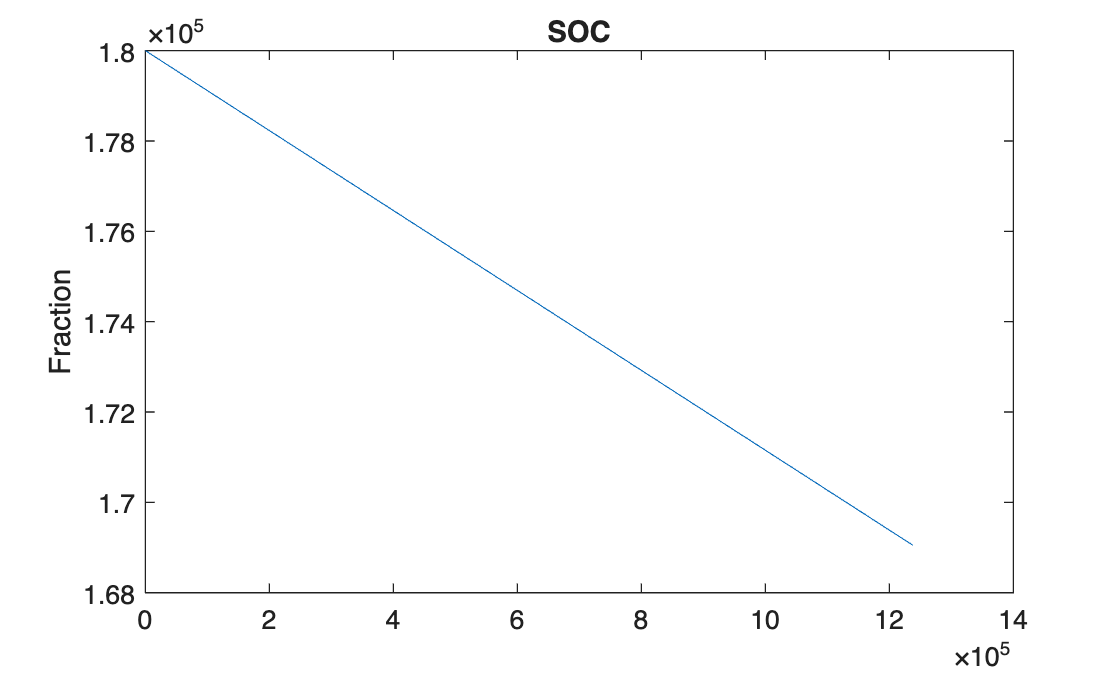

plot(out.soc_log.Data); title('SOC'); ylabel('Fraction');

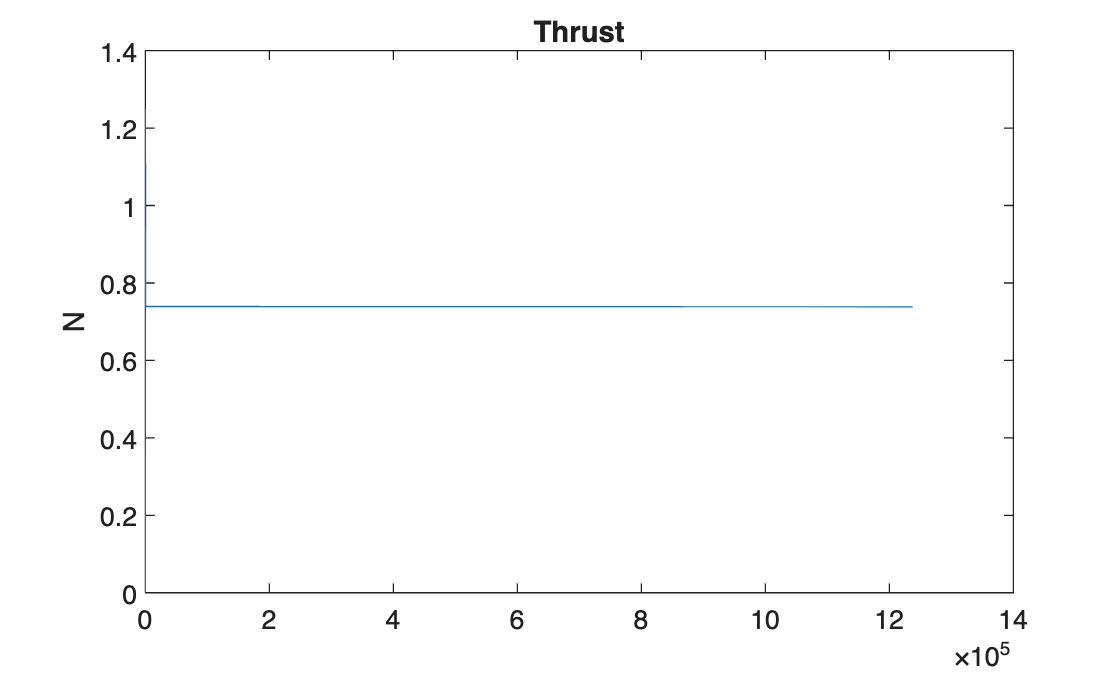

plot(out.thrust_log.Data); title('Thrust'); ylabel('N');